**Acoustic Modem Decoder**

% load short_modem_rx.mat
load long_modem_rx.mat
% load custom_modem_rx.mat

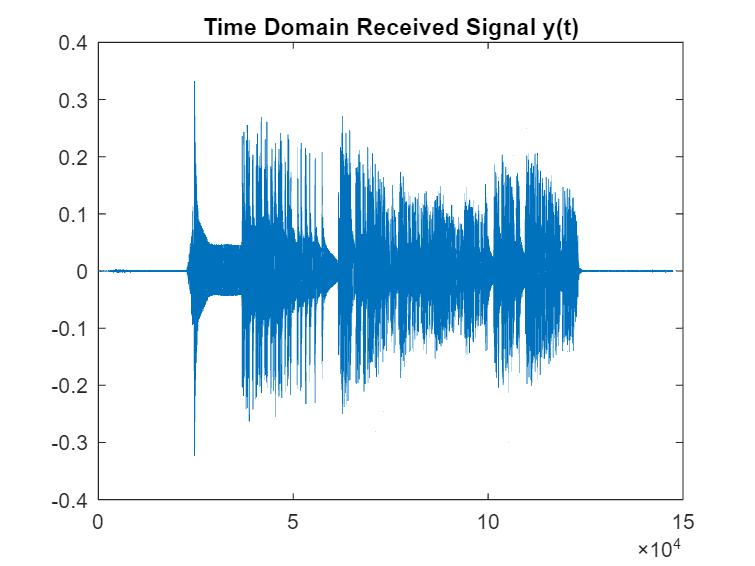

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 
plot(y_r)
title("Time Domain Received Signal y(t)")
saveas(gcf, "1. Time Domain Received Signal.png")

start_idx = find_start_of_signal(y_r,x_sync);

% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

% cut down to message length
bits_per_char = 8;
% SymbolPeriod = 100;
y_t = y_t(1:msg_length*bits_per_char*SymbolPeriod);

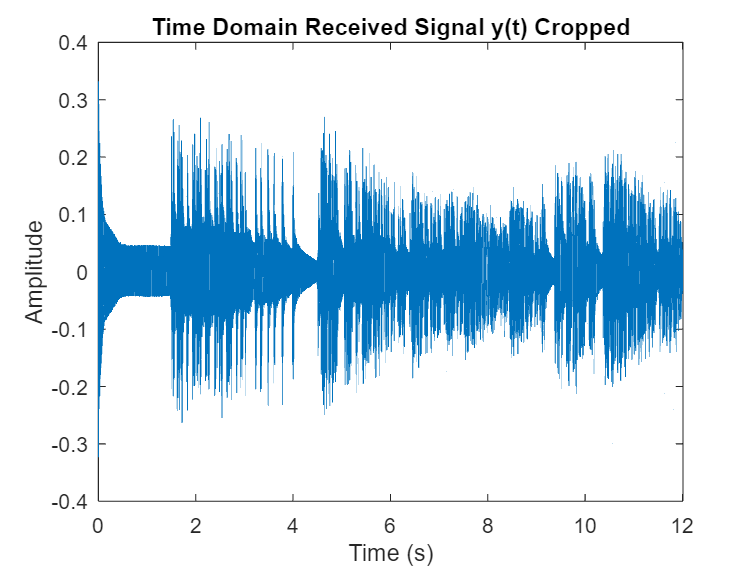

t = [0:length(y_t)-1]./Fs;
plot_time_graph(t, y_t);
title("Time Domain Received Signal y(t) Cropped")
saveas(gcf, "2. Time Domain Received Signal Cropped.png")

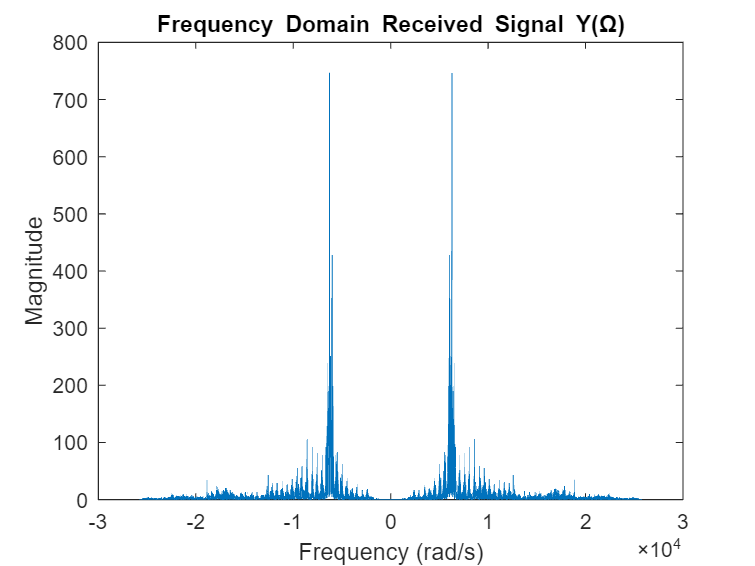


plot_ft_rad(y_t, Fs);
title("Frequency Domain Received Signal Y(\Omega)")
saveas(gcf, "3. Frequency Domain Received Signal.png")

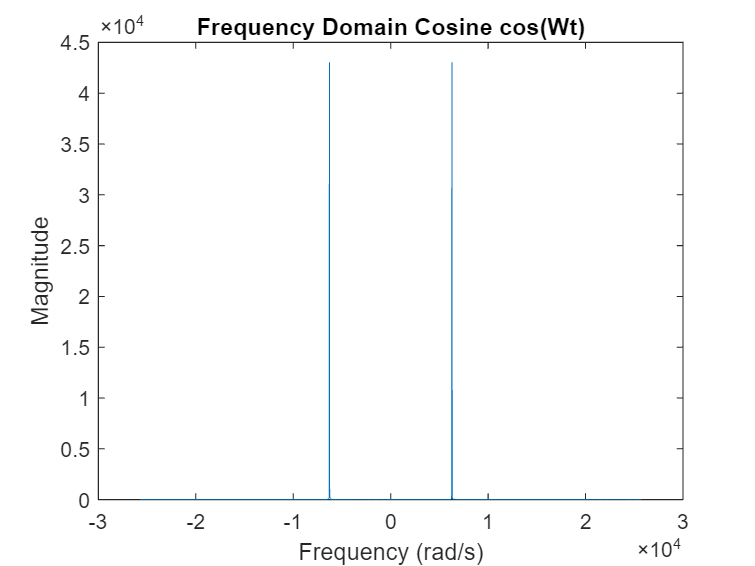

W = 2*pi*f_c; % cutoff frequency of lowpass filter and frequency of cosine
cosine_signal = cos(W*t');

% plot_time_graph(t, cosine_signal);
% title("Time Domain Cosine cos(2\pif_ct")
% saveas(gcf, "4. Time Domain Cosine.png")

plot_ft_rad(cosine_signal, Fs);
title("Frequency Domain Cosine cos(Wt)")
saveas(gcf, "5. Frequency Domain Cosine.png")

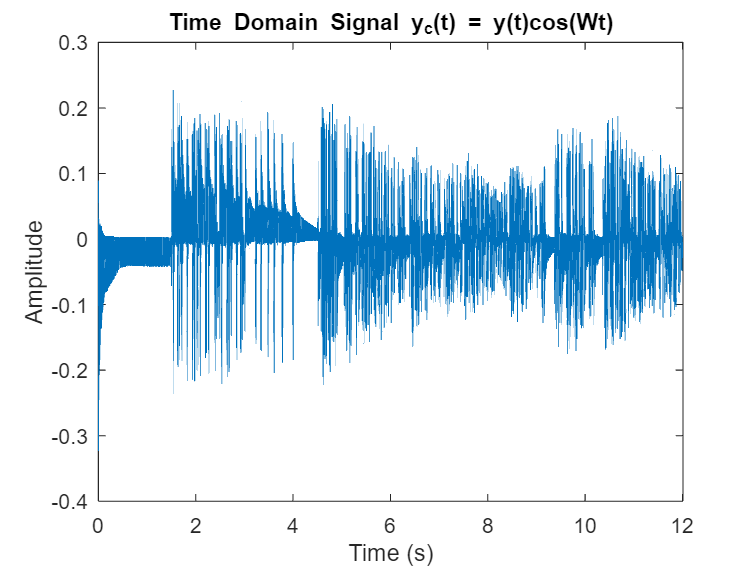

y_c = y_t.*cosine_signal;
plot_time_graph(t, y_c);
title("Time Domain Signal y_{c}(t) = y(t)cos(Wt)")
saveas(gcf, "6. Time Domain Signal yc.png")

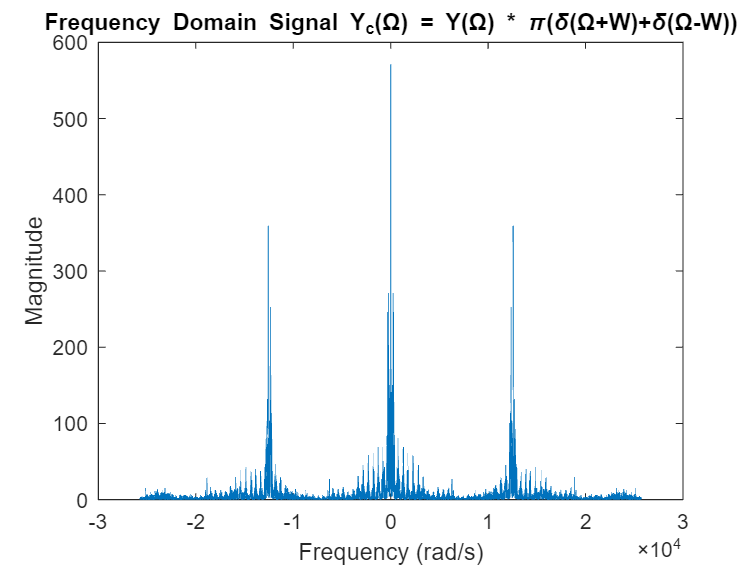


plot_ft_rad(y_c, Fs);
% title("Frequency Domain Signal Y_{c}(\Omega) = Y(\Omega) * FT(cos(2\pif_{c}t))")
title("Frequency Domain Signal Y_{c}(\Omega) = Y(\Omega) * \pi(\delta(\Omega+W)+\delta(\Omega-W))")
saveas(gcf, "7. Time Domain Signal Yc.png")

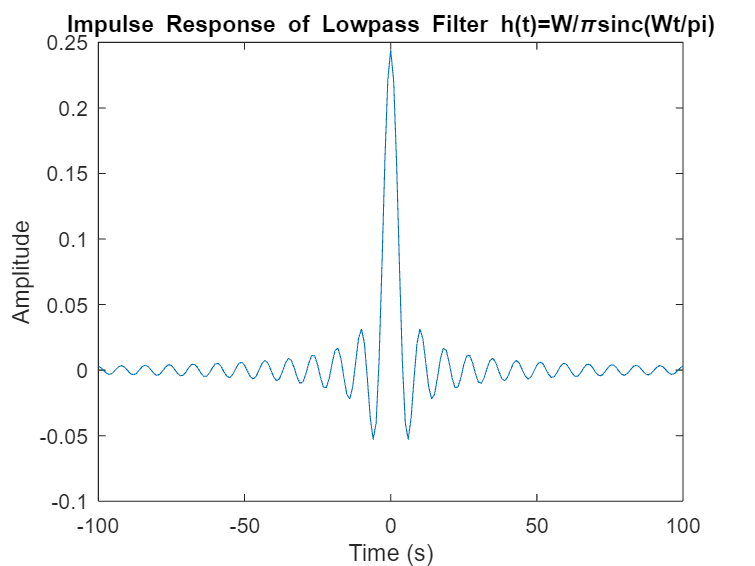

n = 100;
tt = [-n:n];
h = W/pi/Fs*sinc(W/pi/Fs*tt');
% h = f_c/Fs*sinc(f_c/Fs*tt'); % What is the right cutoff freq for lowpass?

plot_time_graph(tt, h);
title('Impulse Response of Lowpass Filter h(t)=W/\pisinc(Wt/pi)');
saveas(gcf, "8. Impulse Response of Lowpass Filter.png")

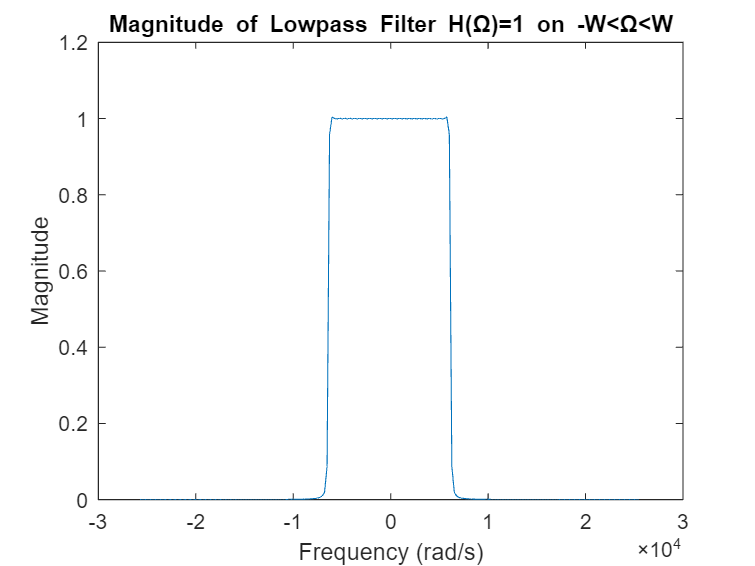


plot_ft_rad(h, Fs);
title('Magnitude of Lowpass Filter H(\Omega)=1 on -W<\Omega<W');
saveas(gcf, "9. Magnitude of Lowpass Filter.png")

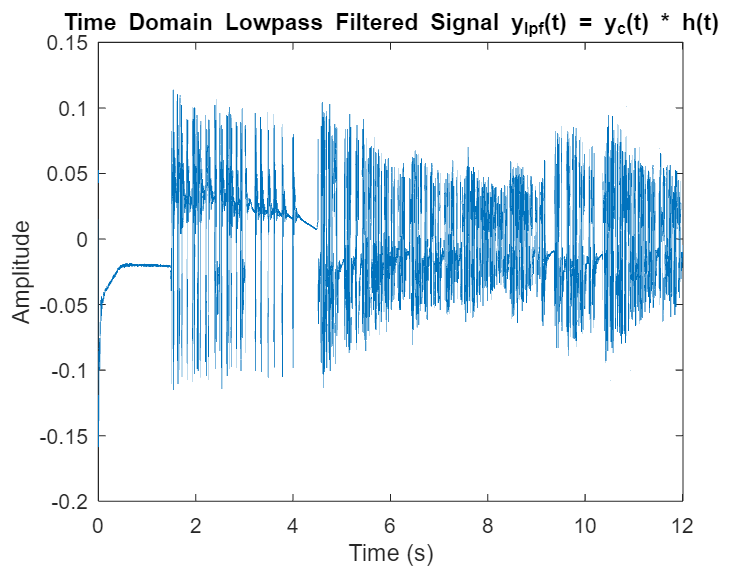

y = conv(y_c, h); % convolve to filter

y_lpf = y(n+1:end-n);
plot_time_graph(t, y_lpf);
title("Time Domain Lowpass Filtered Signal y_{lpf}(t) = y_{c}(t) * h(t)")
saveas(gcf, "10. Time Domain Lowpass Filtered Signal.png")

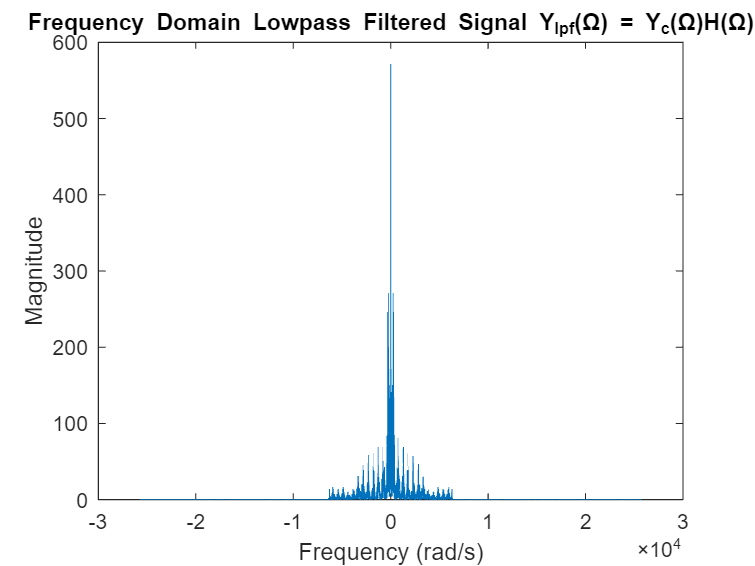


plot_ft_rad(y_lpf, Fs); % plot the magnitude of the FT
title("Frequency Domain Lowpass Filtered Signal Y_{lpf}(\Omega) = Y_{c}(\Omega)H(\Omega)")
saveas(gcf, "11. Frequency Domain Lowpass Filtered Signal.png")

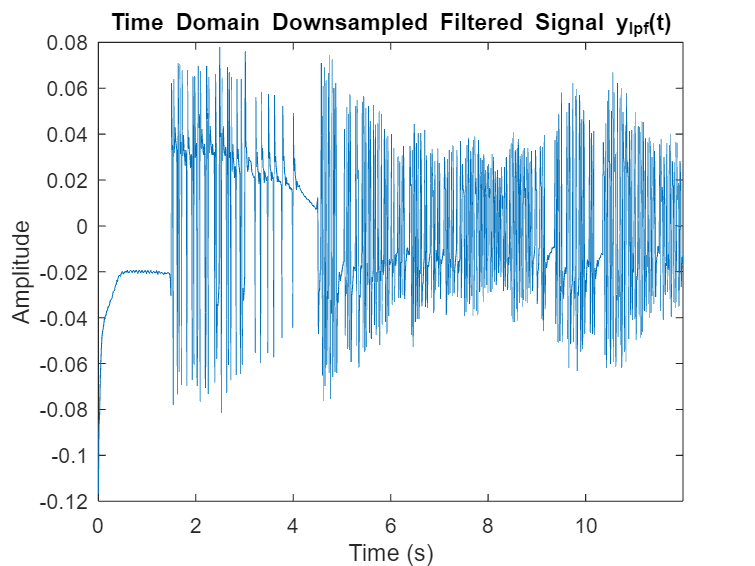

y_dn = downsample(y_lpf(SymbolPeriod/2:end), SymbolPeriod);
t_dn = downsample(t, SymbolPeriod);

plot_time_graph(t_dn, y_dn)
title("Time Domain Downsampled Filtered Signal y_{lpf}(t)")
saveas(gcf, "12. Time Domain Downsampled Filtered Signal.png")


% depending on sign:
message = y_dn > 0

message = 984×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


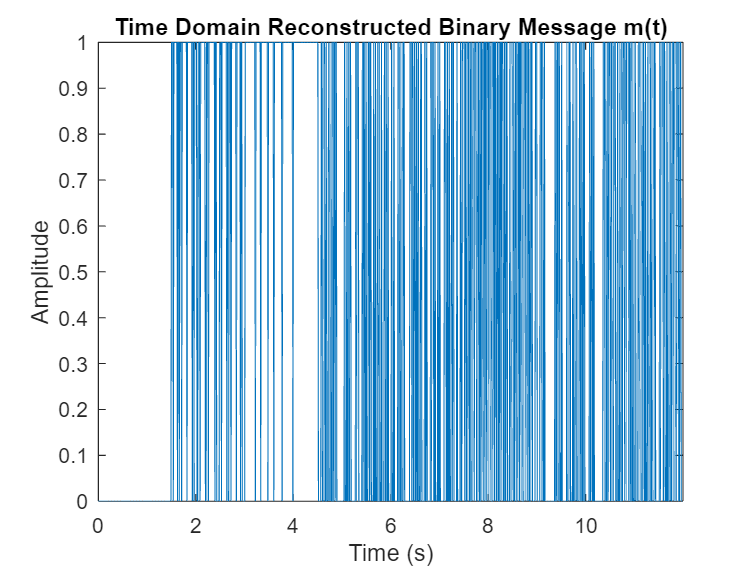

% message = y_dn < 0

plot_time_graph(t_dn, message)
title("Time Domain Reconstructed Binary Message m(t)")
saveas(gcf, "13. Time Domain Reconstructed Binary Message.png")


% convert to a string assuming that x_d is a vector of 1s and 0s representing the decoded bits
BitsToString(message)

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'

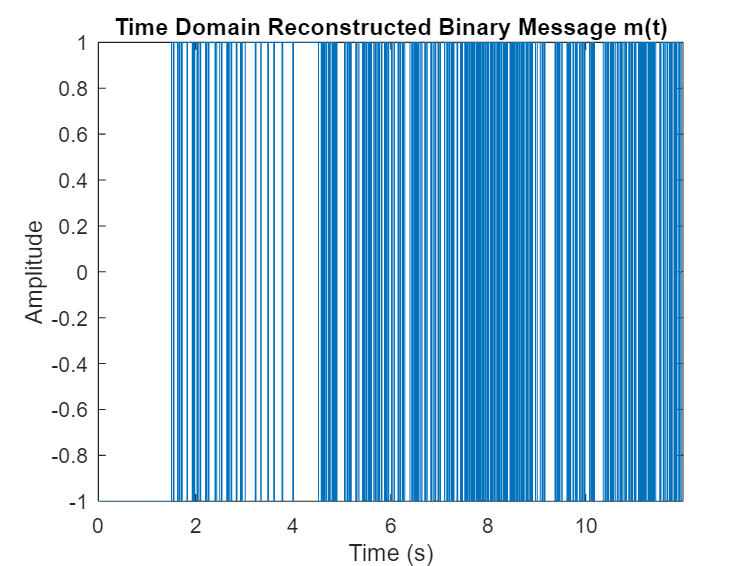

m_up = upsample(message*2-1, 2); m_up(2:2:end) = m_up(1:2:end);
t_up = upsample(t_dn, 2); t_up(2:2:end-1) = t_up(3:2:end); t_up(end) = max(t_up);
plot_time_graph(t_up, m_up)
title("Time Domain Reconstructed Binary Message m(t)")
saveas(gcf, "14. Time Domain Reconstructed Binary Message.png")

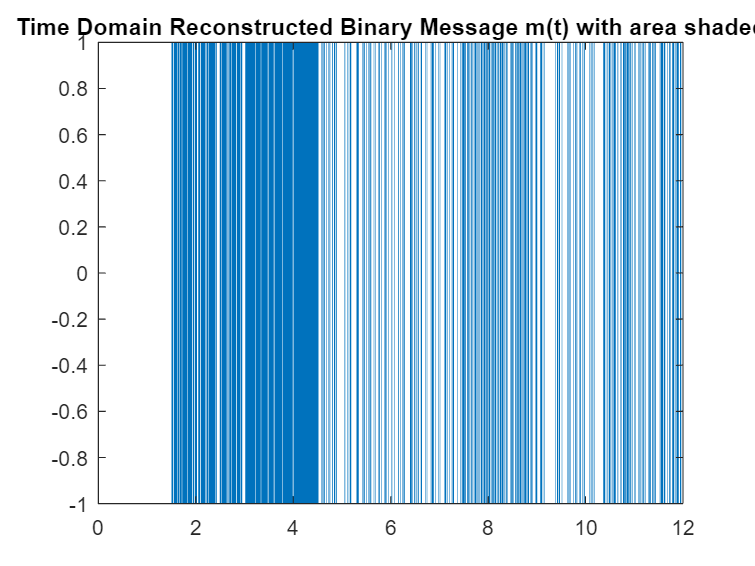


area(t_up, m_up, -1, 'LineStyle','none')
ylim([-1,1])
title("Time Domain Reconstructed Binary Message m(t) with area shaded")
saveas(gcf, "15. Time Domain Reconstructed Binary Message with area shaded.png")

function plot_time_graph(t, x)
    plot(t, x); xlabel('Time (s)'); ylabel('Amplitude')
    xlim([min(t), max(t)])
end